## Generate signals from Gaussian Distribution

sample_size = [10000, 1]

sample_size =        10000           1


% Generate: x, v - true values from a gaussian distribution: 
x_mean = 2; 
v_mean = 3; 
x_var = 1; 
v_var = 1; 
x = normrnd(x_mean, x_var, sample_size);
v = normrnd(v_mean, v_var, sample_size);

## Compute Observations from these distributions: 

%create Observation
a = 2; b=1; 
y = a*x+b*v;



## Predict x

x_predict = predict(y, x_mean, v_mean, x_var, v_var, a, b); 

x_predict =     2.0323
    2.1181
    2.0301
    1.9185
    2.0151
    1.9615
    2.1011
    1.8976
    1.8540
    1.8817


error = x - x_predict; 

error =     0.4566
    0.9165
    0.6968
   -0.2219
    0.2788
   -0.7488
    0.7873
   -1.0447
   -0.9228
   -0.6912


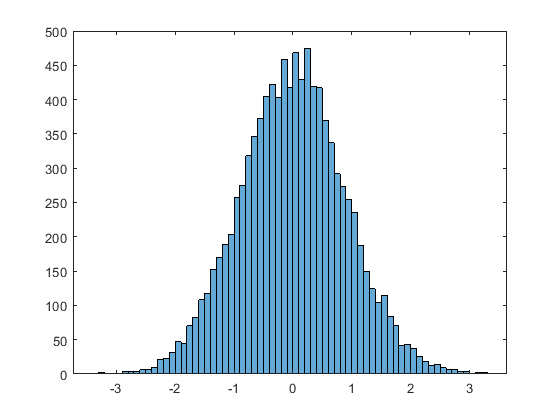

histogram(error)